# Homework04 - Random Numbers

## Randomness tests

### (1) Moment

Moment of discrete distribution is $$$\langle x^k \rangle=\frac{1}{N} \sum_{i=1}^N x_i^k.$

First, vary k and plot moment v.s. k to see if the moment is about $\frac{1}{k+1}$. Let's choose the first five moments.

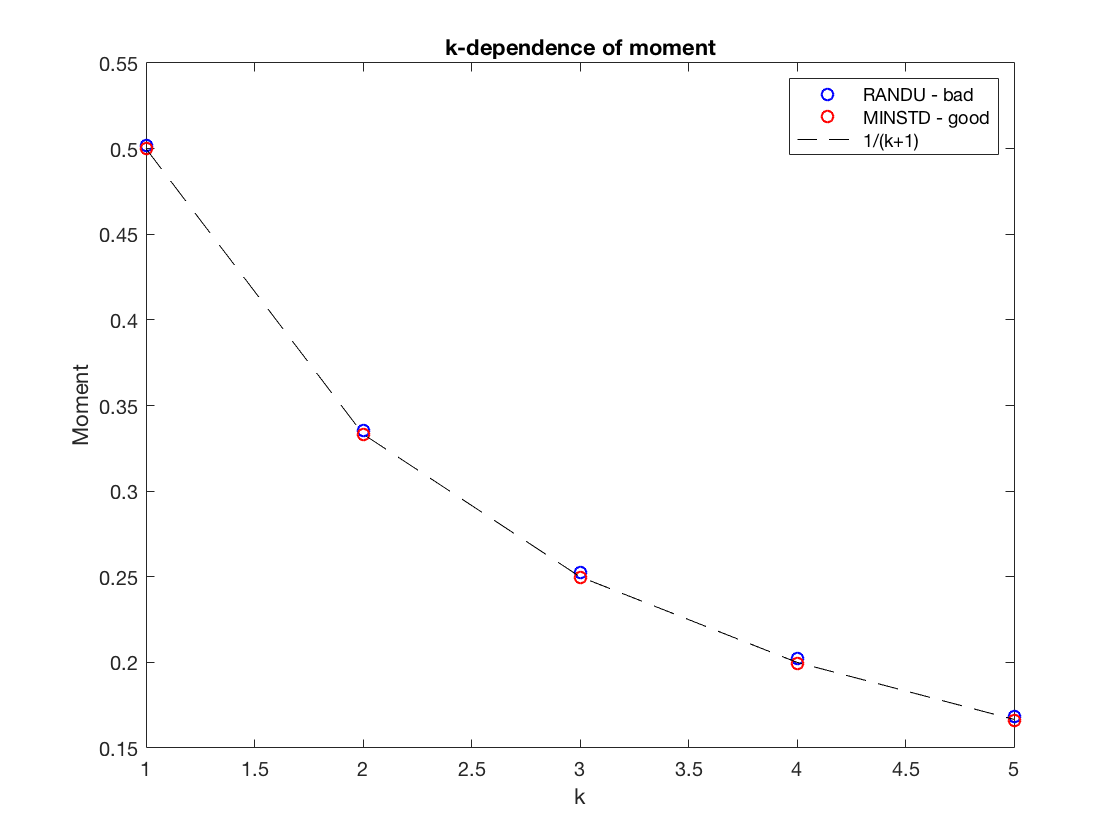

N = 50000;

% RANDU - Bad choice
coef1 = 65539;
bigint1 = 2^31;

% MINSTD - Good choice
coef2 = 7^5;
bigint2 = 2^31-1;    

r1 = Lehmer(N,coef1,bigint1,1);
r2 = Lehmer(N,coef2,bigint2,1);

k = [1 2 3 4 5];
for i=1:5
    m1=0;
    m2=0;
    for j=1:N
        m1 = m1 + r1(j,1).^k;
        m2 = m2 + r2(j,1).^k;
    end
    m1=m1/N;
    m2=m2/N;
end

figure
plot(k,m1,'bo',k,m2,'ro',k,1./(k+1),'k--')
xlabel('k')
ylabel('Moment')
title('k-dependence of moment')
legend('RANDU - bad','MINSTD - good','1/(k+1)')

It seems RANDU is still good here. Next we keep k fixed at k = 2, and test different N to see if the deviation of moment to $\frac{1}{k+1}$ varies as $\frac{1}{\sqrt{N}}$

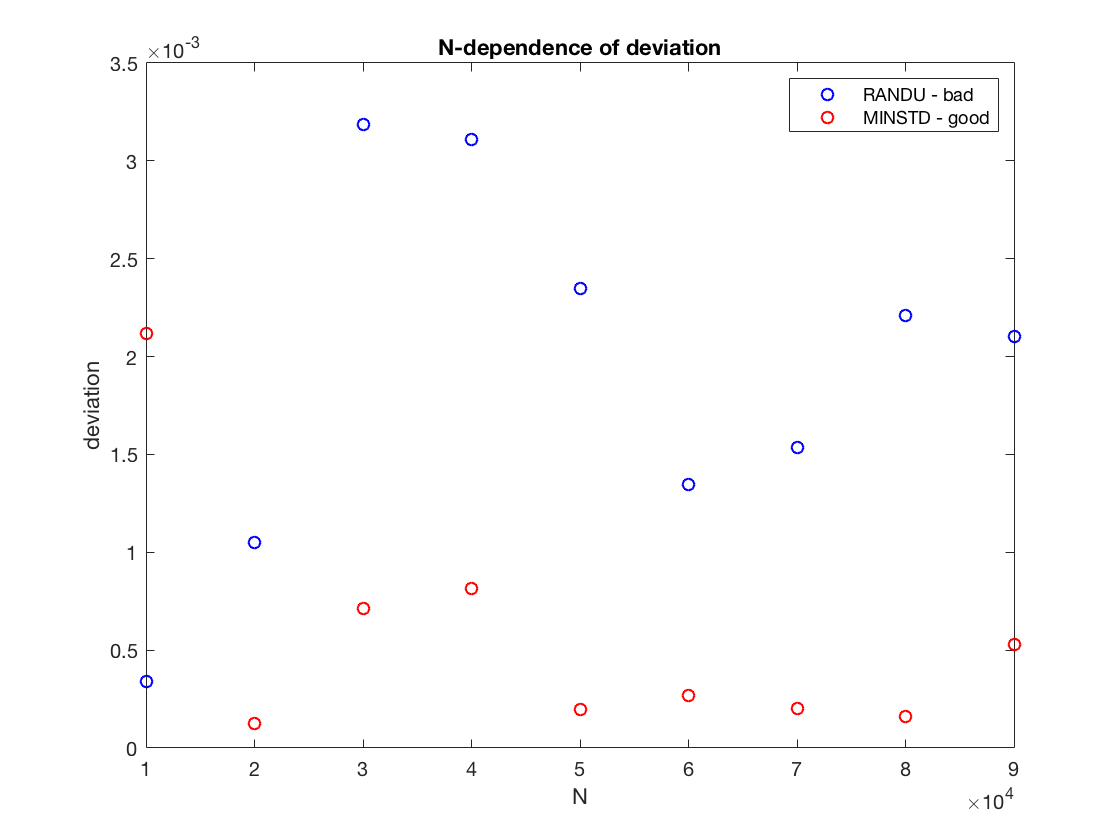

k = 2;
N_list = 10000*[1 2 3 4 5 6 7 8 9];
dev1_list = zeros(length(N_list),1);
dev2_list = zeros(length(N_list),1);

for i=1:length(N_list)
    N = N_list(i);

    % RANDU - Bad choice
    coef1 = 65539;
    bigint1 = 2^31;
    
    % MINSTD - Good choice
    coef2 = 7^5;
    bigint2 = 2^31-1;    

    r1 = Lehmer(N,coef1,bigint1,1.);
    r2 = Lehmer(N,coef2,bigint2,1.);

    m1=0;
    m2=0;
    for j=1:N
        m1 = m1 + r1(j,1)^k;
        m2 = m2 + r2(j,1)^k;
    end
    m1=m1/N;
    m2=m2/N;
    dev1_list(i) = abs(m1 - 1/(k+1));
    dev2_list(i) = abs(m2 - 1/(k+1));

end

plot(N_list,dev1_list,'bo',N_list,dev2_list,'ro')
xlabel('N')
ylabel('deviation')
title('N-dependence of deviation')
legend('RANDU - bad','MINSTD - good')

Two set of parameters work fine, the deviation is at the order of 10^-3 and we do not see any N dependence. So RANDU does not fail in this test.

### (2) **Autocorrelation**

Near-neighbor correlation $C(m)=\langle x_i x_{i+m} \rangle = \frac{1}{N} \sum_{i=1}^N {x_ix_{i+m}}$

Compare with $\int _0^1 {dx \int _0^1{dy P(x,y)xy}} = \frac{1}{4}$

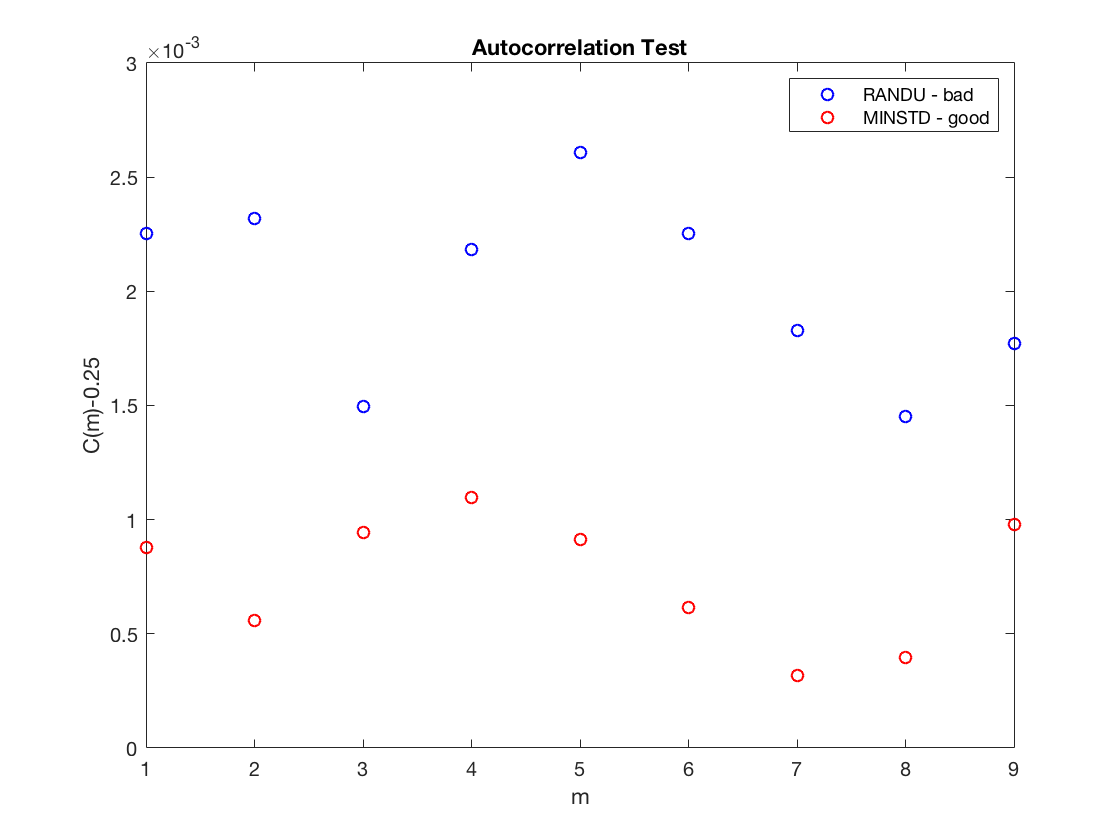

m_list = [1 2 3 4 5 6 7 8 9];
C1_list = zeros(9,1);
C2_list = zeros(9,1);

for j=1:9
    m = m_list(j);
    M = N-m;
    C1=0;
    C2=0;
    for i=1:M
        C1 = C1 + r1(i,1)*r1(i+m,1);
        C2 = C2 + r2(i,1)*r2(i+m,1);
    end
    C1_list(j) = C1/M;
    C2_list(j) = C2/M;
end

figure
plot(m_list,C1_list-0.25,'bo',m_list,C2_list-0.25,'ro')
xlabel('m')
ylabel('C(m)-0.25')
title('Autocorrelation Test')
legend('RANDU - bad','MINSTD - good')

We notice that C(m) is about 0.25 for both set of parameters. So both generators pass this test.

### (3) Visual test

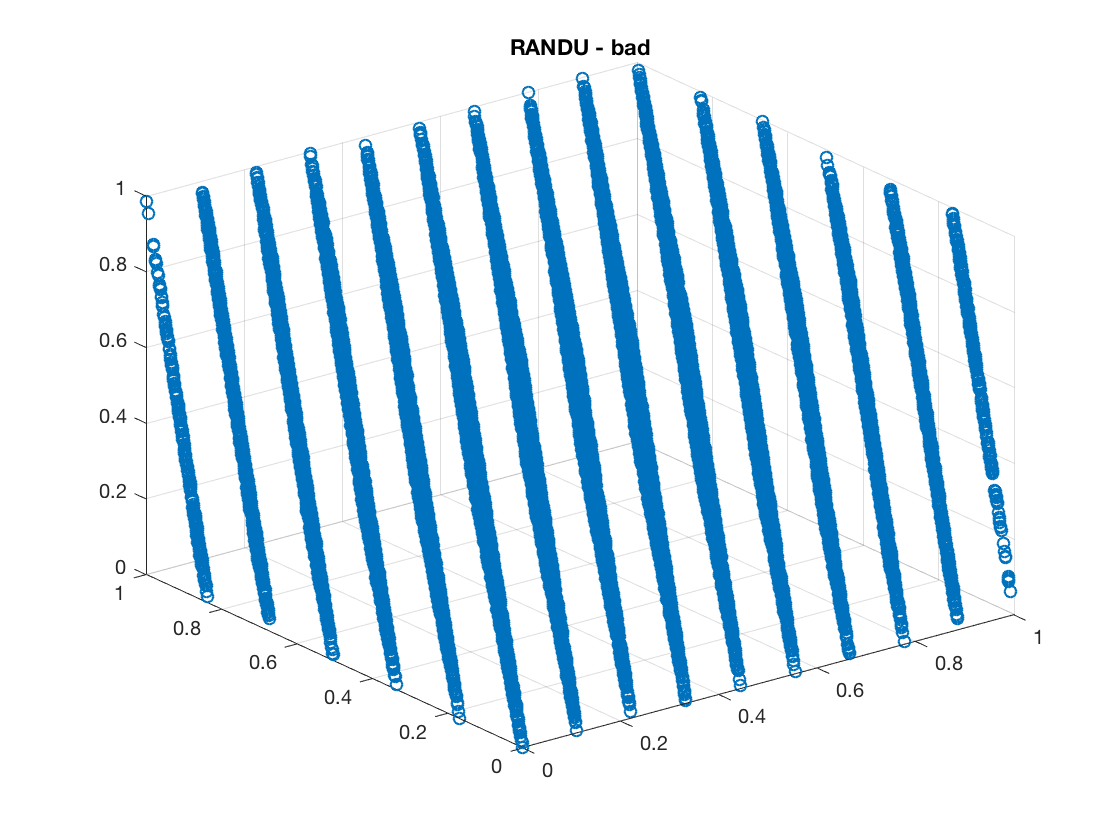

N3 = (N-mod(N,3))/3;
r11 = zeros(N3,1);
r12 = zeros(N3,1);
r13 = zeros(N3,1);
r21 = zeros(N3,1);
r22 = zeros(N3,1);
r23 = zeros(N3,1);
for i=1:N3
    r11(i) = r1(3*i-2);
    r12(i) = r1(3*i-1);
    r13(i) = r1(3*i);
    
    r21(i) = r2(3*i-2);
    r22(i) = r2(3*i-1);
    r23(i) = r2(3*i);
end
figure
scatter3(r11,r12,r13)
title('RANDU - bad')

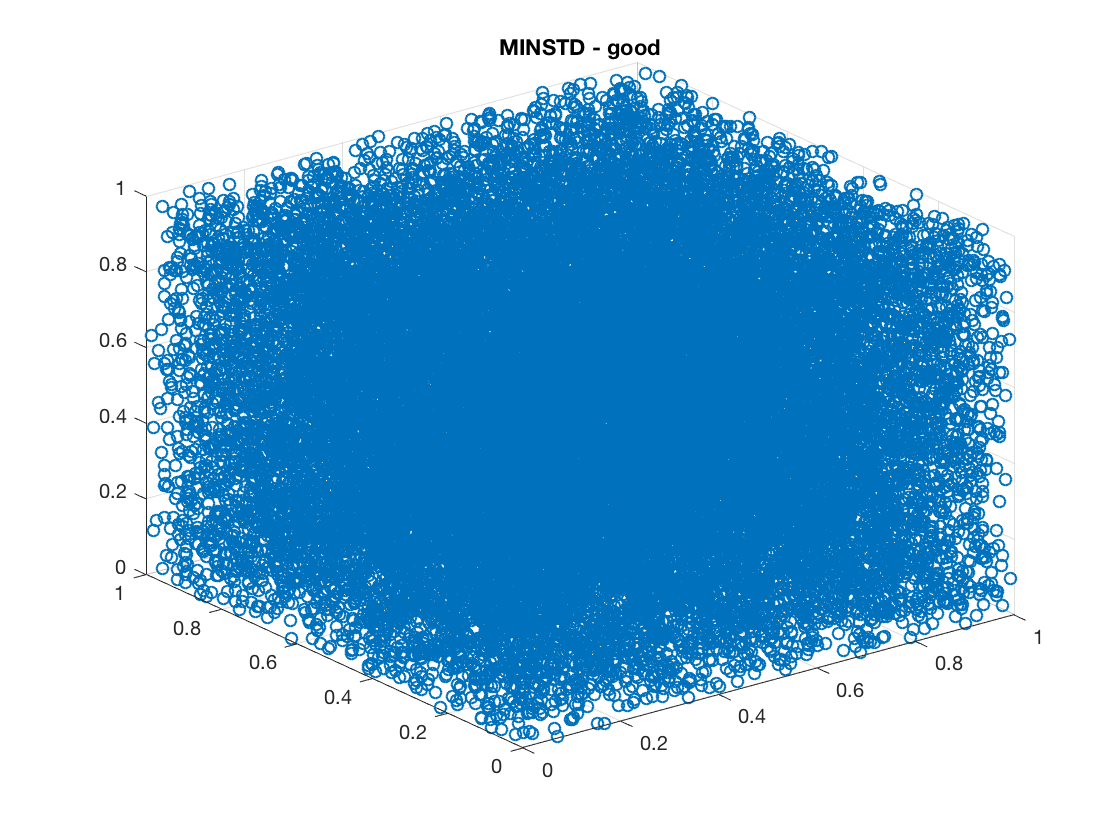

figure
scatter3(r21,r22,r23)
title('MINSTD - good')

We can see there exists some regular patterns if we plot 'random' numbers from RANDU - this is a sign of failing the visual test, while MINSTD still good. 

### (4) Statistical error

We put this random numbers into a logrithm function to see if it satisfy the distribution.

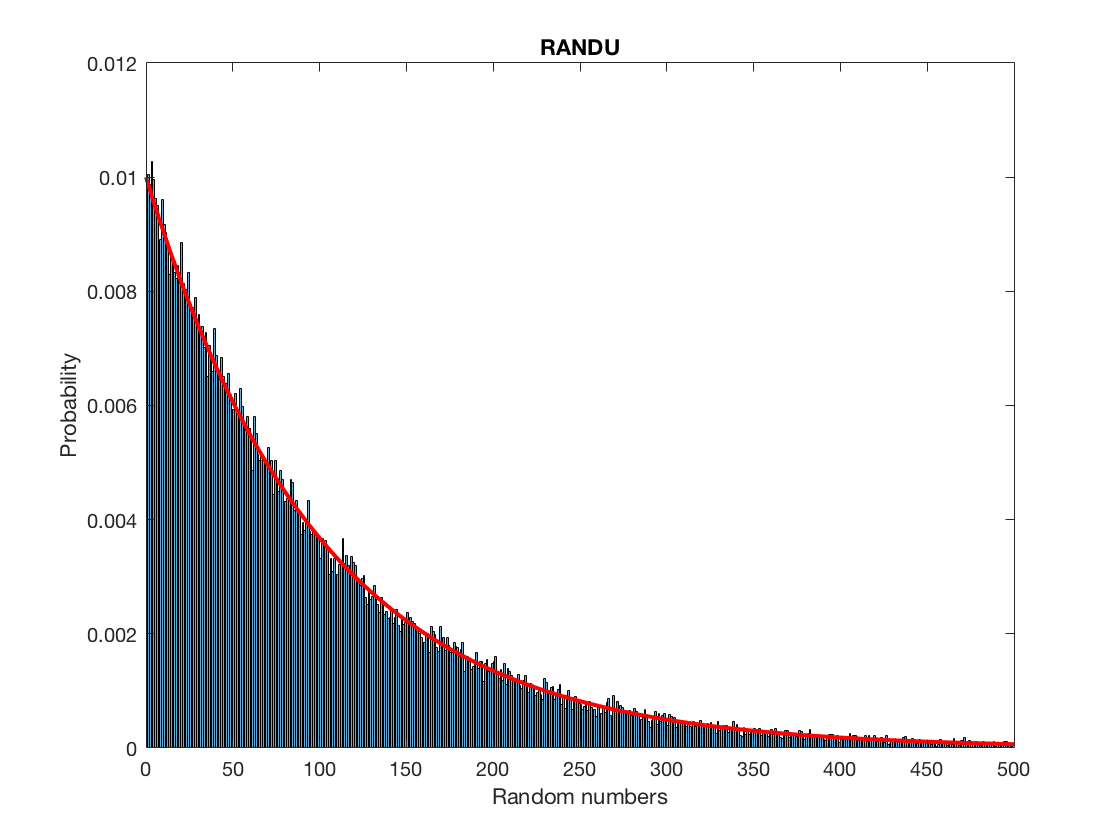

xlambda = 0.01;
x1 = -log(r1)/xlambda;
x2 = -log(r2)/xlambda;

binwidth = xlambda;
figure
histogram(x1,'BinWidth',100*binwidth,'Normalization','probability')
hold on
plot([0:binwidth:500],xlambda*exp(-xlambda.*[0:binwidth:500]),'r','LineWidth',2)
xlabel('Random numbers')
ylabel('Probability')
xlim([0 500])
title('RANDU')

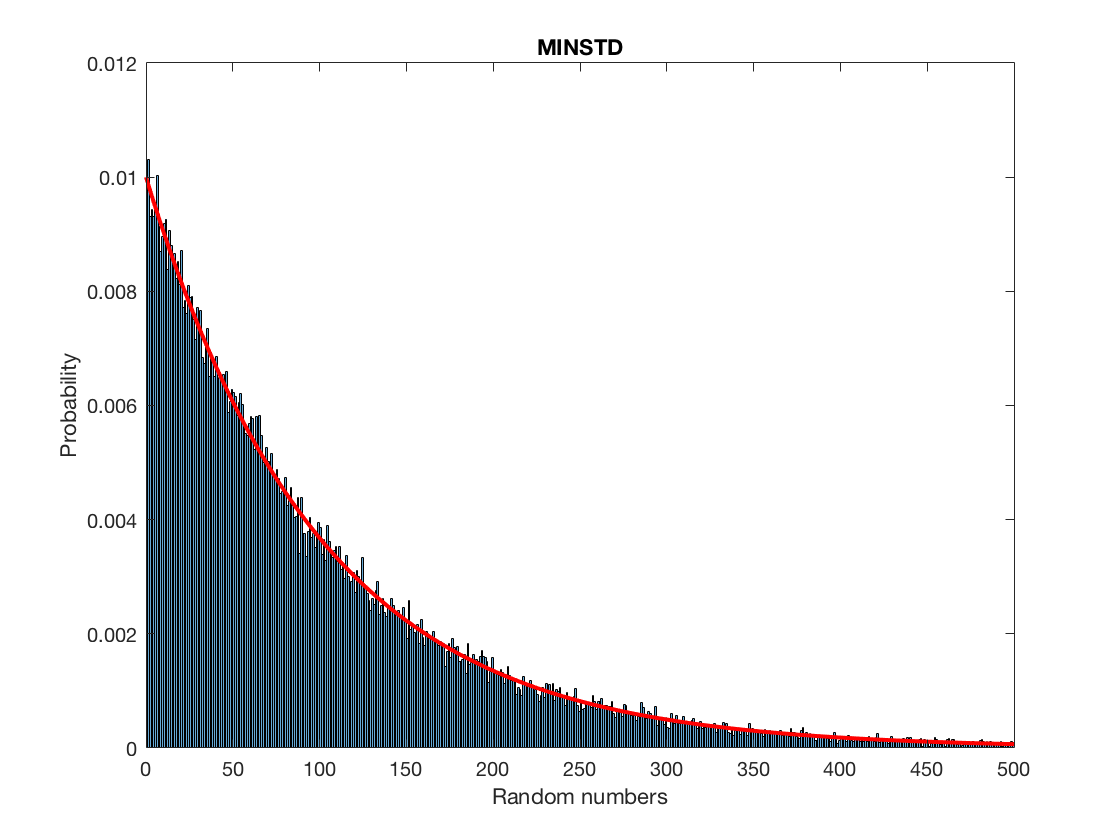


figure
histogram(x2,'BinWidth',100*binwidth,'Normalization','probability')
hold on
plot([0:binwidth:500],xlambda*exp(-xlambda.*[0:binwidth:500]),'r','LineWidth',2)
xlabel('Random numbers')
ylabel('Probability')
xlim([0 500])
title('MINSTD')

RANDU and MINSTD both pass the statistical test.

function r = Lehmer(N,coef,bigint,seed)
% Lehmer random number generator
% generates r in (0,1)
    r = zeros(N,1);
    r(1,1)=seed;
    for i=2:N
        r(i,1) = mod((coef * r(i-1,1)) , bigint);
    end
    r = r/bigint;
end